# Multinomial Logistic Regression


$$\ln \left(\frac{\Pi \textrm{versiscolor}}{\Pi \textrm{virginica}}\right)=\beta_0 +\beta_1 X_1 +\beta_2 X_2 +\beta_3 X_3 +\beta_4 X_4$$


### Data

load fisheriris
catNames = {'setosa','versicolor','virginica'};
T = table();
T.X1 = meas(:,1);
T.X2 = meas(:,2);
T.X3 = meas(:,3);
T.X4 = meas(:,4);
T.Species = categorical(species,catNames);

**Build a Logistic Regression Model**

X = T{:,1:4};
[B,dev,stats] = mnrfit(X,T.Species);

### Validate model

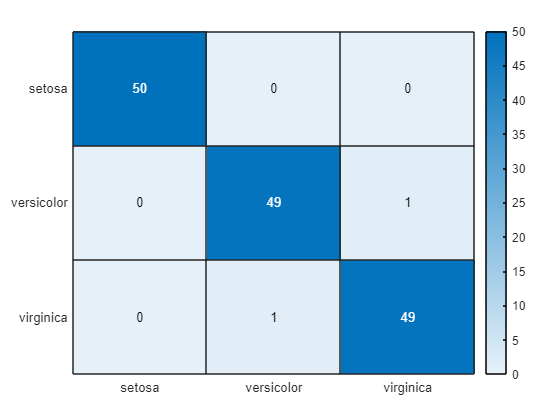

pihat = mnrval(B,X);
[~,idx] = max(pihat,[],2);
T.SpeciesPredicted = categorical(catNames(idx)',catNames);

[Matrix_ActualVsEstimated,order] = confusionmat(T.Species,T.SpeciesPredicted);
figure
heatmap(catNames,catNames,Matrix_ActualVsEstimated)